Reading the Image

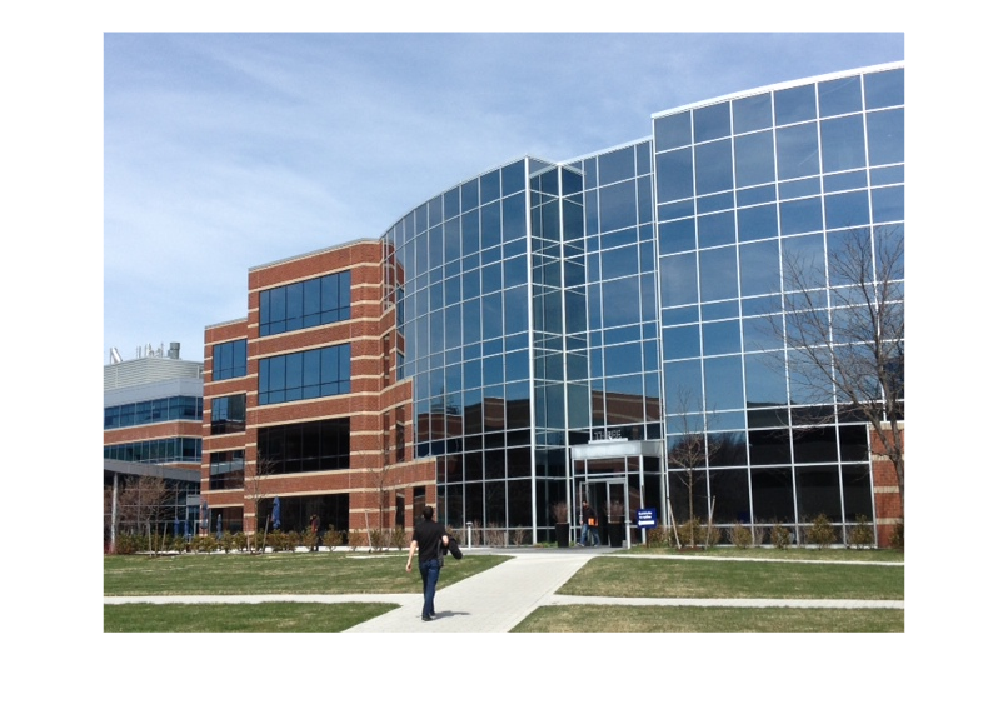

building = imread("building1.jpg");
imshow(building)

buildingGray = im2gray(building);

Detecting corners using Harris-stephens algorithm

corners = detectHarrisFeatures(buildingGray)

corners =   790×1 cornerPoints array with properties:

    Location: [790×2 single]
      Metric: [790×1 single]
       Count: 790


corners.Location

ans = 790×2 single matrix
    6.0607  385.3246
    9.1022  264.2226
    9.6145  365.2691
   10.5189  353.8413
   13.0878  263.3986
   27.2650  416.2011
   35.6434  456.5956
   38.1914  255.1824
   43.5418  416.2651
   48.0541  416.1169


corners.Metric

ans = 790×1 single column vector
    0.0004
    0.0004
    0.0004
    0.0003
    0.0009
    0.0004
    0.0004
    0.0003
    0.0048
    0.0017


corners.Count

ans = 790

Display corner features 

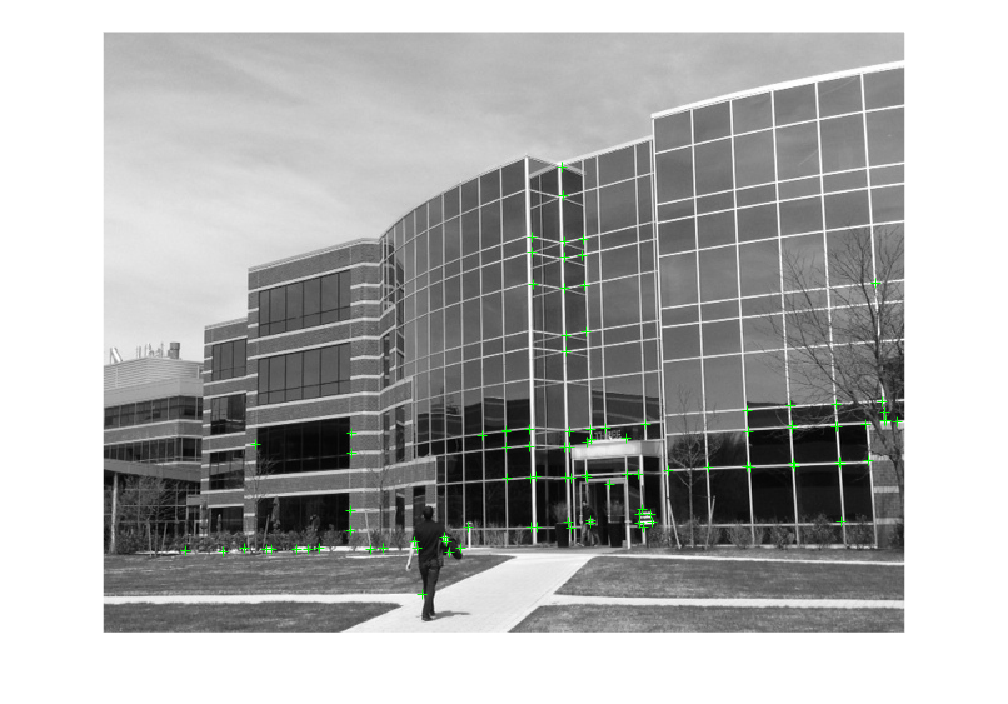

imshow(buildingGray);
hold on;
strongestCorners = selectStrongest(corners, 100);
plot(strongestCorners);
hold off;

Detecting Blob (The workflow will be similar )

using SURF (Speeded Up Robust Features)

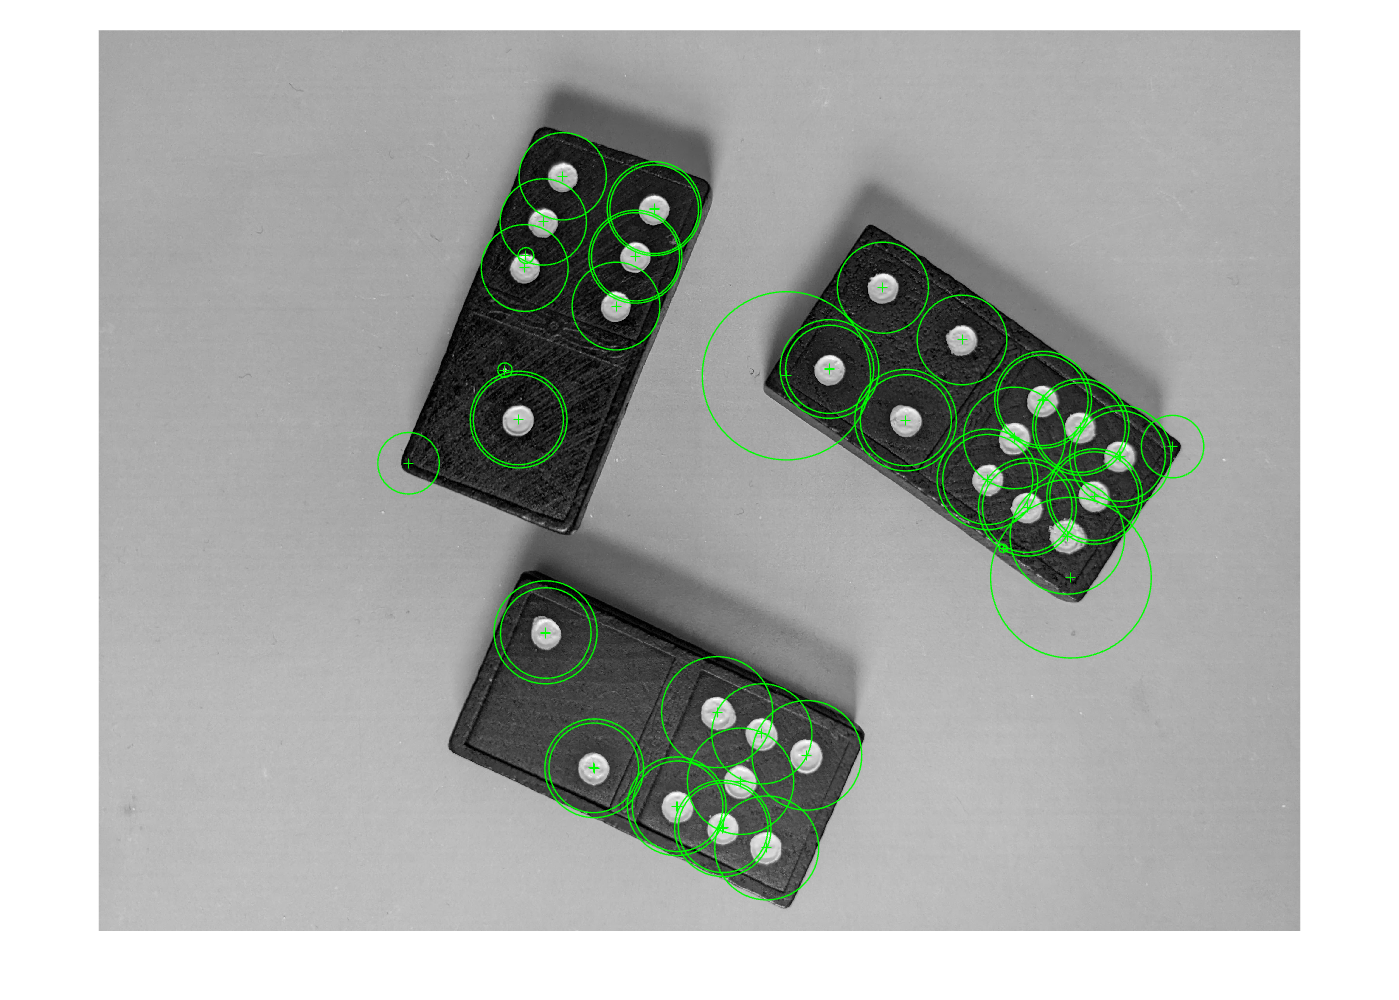

dominos = imread("dominos.jpg");
dominosBW = im2gray(dominos);
blobs = detectSURFFeatures(dominosBW, "NumOctaves", 5);
strongestBlobs = selectStrongest(blobs, 50);

imshow(dominosBW);
hold on;
plot(strongestBlobs);
hold off;

Detecting Uniform Intensity Regions 

using MSER (Maximally Stable Extremal Regions )

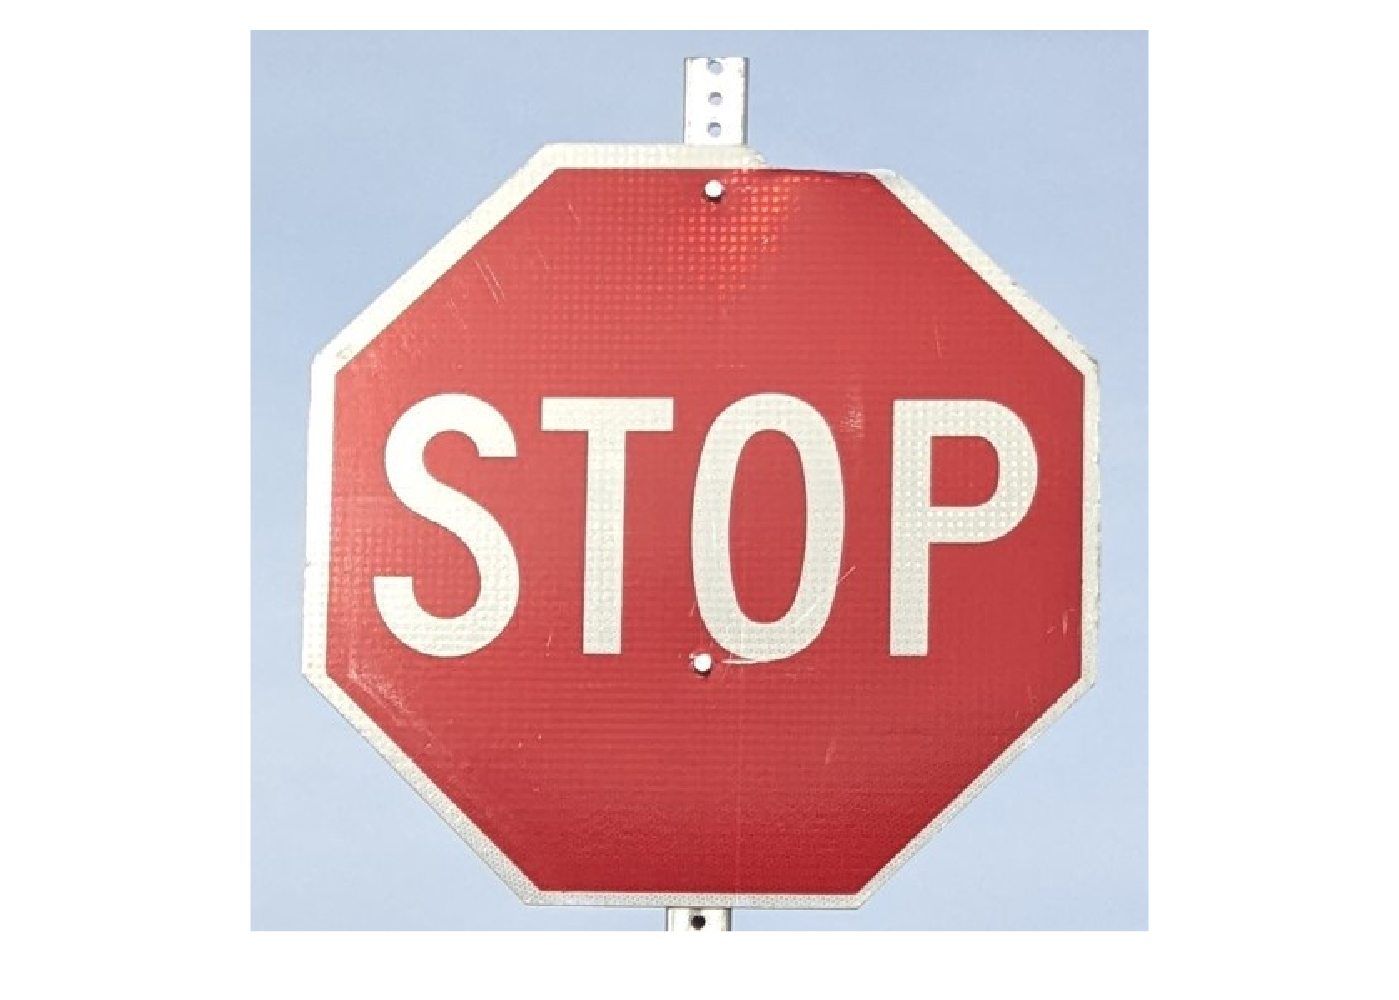

stop = imread("stopSign.jpg");

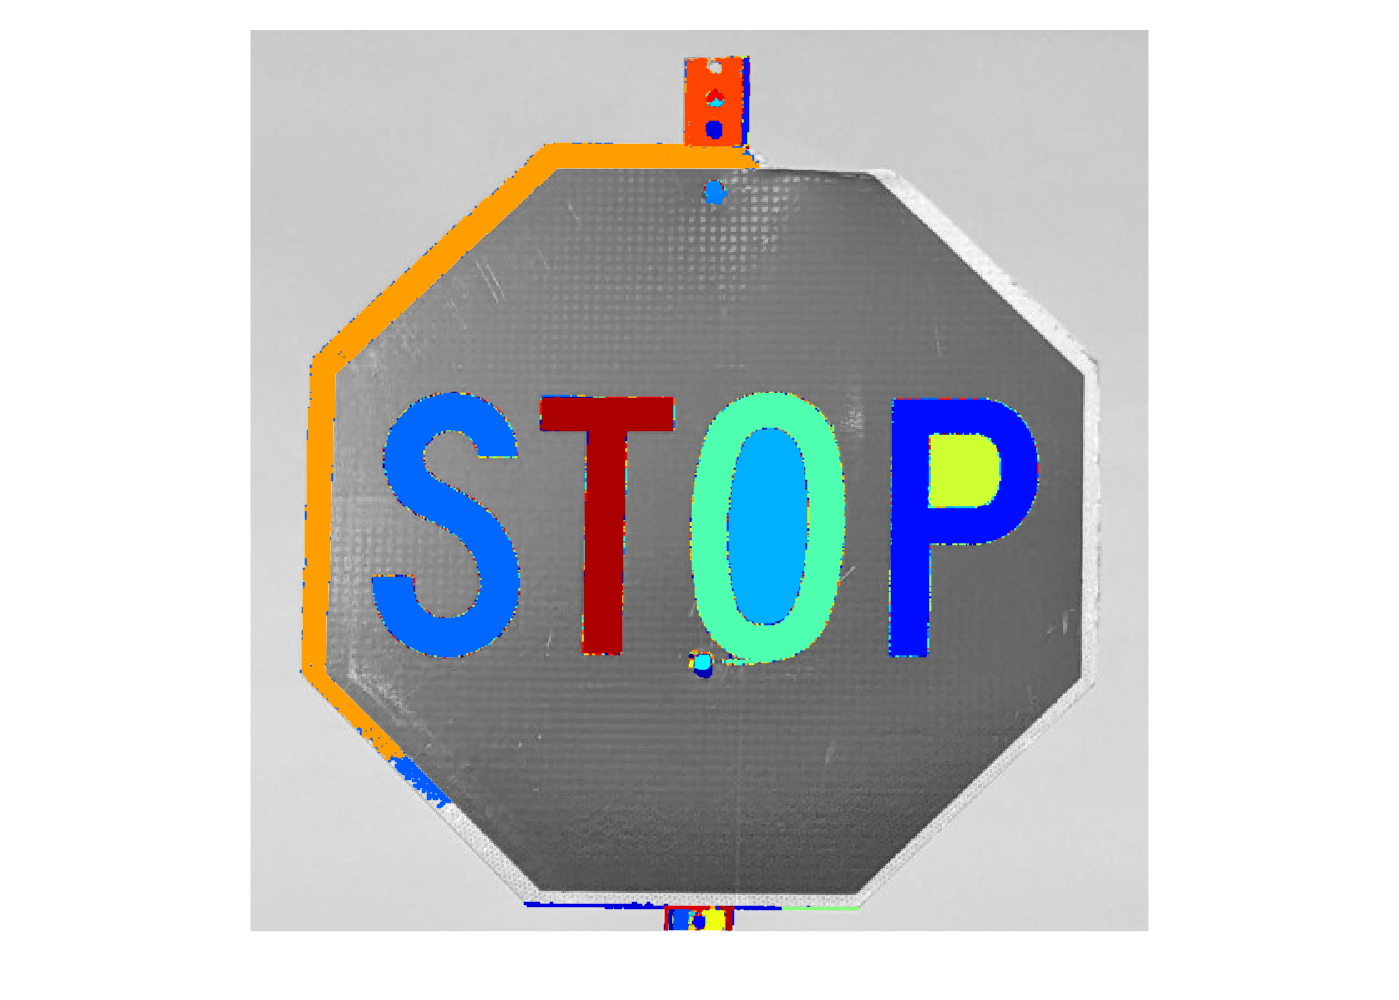

stopBW = im2gray(stop);

regions = detectMSERFeatures(stopBW);
imshow(stopBW);
hold on;
plot(regions, "showPixelList", true, "showEllipses", false);
hold off